addpath('resources','scripts');
clear

## Question 2.1

Create a sequence x sampled at 10 Hz in [􀀀10; 10].

Calculate the function values cos(2x) and sin(2x). 

Calculate the fast Fourier transform (fft) for each of these sequences of function values and plot them.

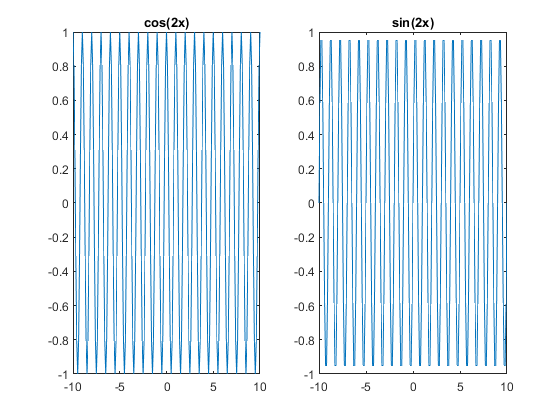

f = 10;
x=-10:0.1:10;

y1 = cos(2*pi*x);
y2 = sin(2*pi*x);

ft1 = fft(y1);
ft2 = fft(y2);

% PLOTS:
% original functions
figure(1)
subplot(1,2,1)
plot(x,y1)
%plot(10*x(1:30),y1(1:30))
title('cos(2x)')
subplot(1,2,2)
plot(x,y2)
%plot(10*x(1:30),y2(1:30))
title('sin(2x)')

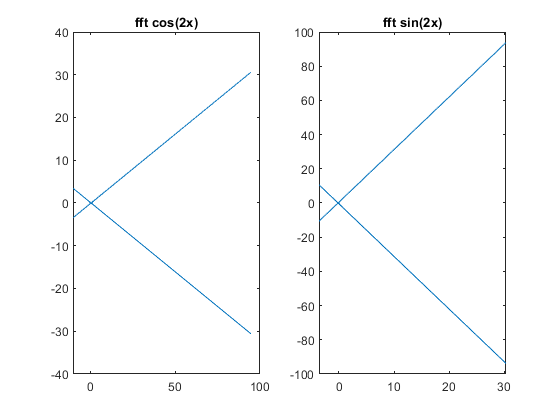

% fft functions
figure(2)
subplot(1,2,1)
plot(ft1)
title('fft cos(2x)')
subplot(1,2,2)
plot(ft2)
title('fft sin(2x)')

# What happens?

## Question 2.2

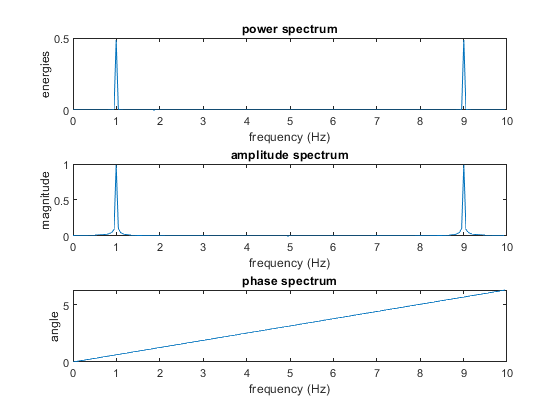

figure('Name','fft(cos(2x)) spectra')
plotfft(ft1,f)

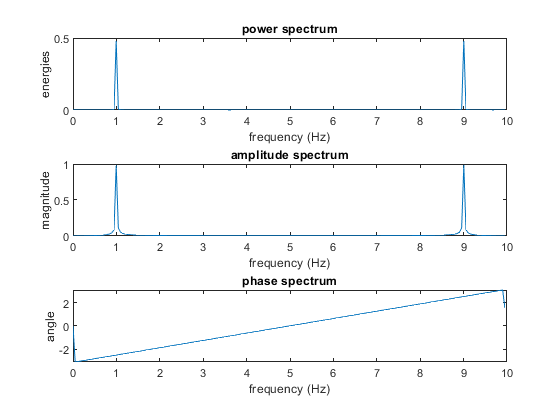


figure('Name','fft(sin(2x)) spectra')

plotfft(ft2,f)

## Question 2.3

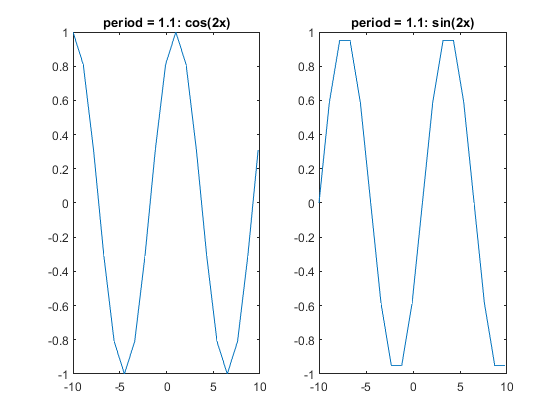

f2 = 1/1.1;
x2=-10:1.1:10;

y21 = cos(2*pi*x2);
y22 = sin(2*pi*x2);

ft21 = fft(y21);
ft22 = fft(y22);

% PLOTS:
% original functions
figure(6)
subplot(1,2,1)
plot(x2,y21)
title('period = 1.1: cos(2x)')
subplot(1,2,2)
plot(x2,y22)
title('period = 1.1: sin(2x)')

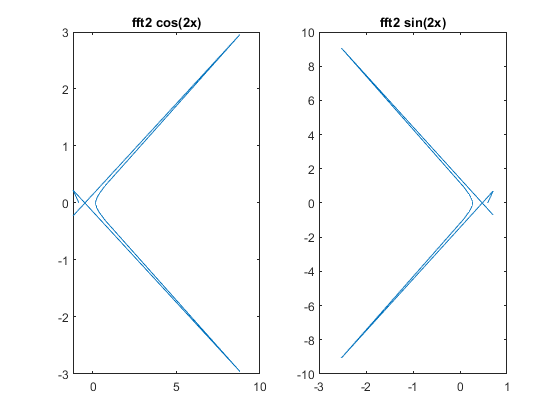

% fft functions
figure(7)
subplot(1,2,1)
plot(ft21)
title('fft2 cos(2x)')
axis auto
subplot(1,2,2)
plot(ft22)
title('fft2 sin(2x)')
axis auto


% spetra
figure('Name','period = 1.1: fft(cos(2x)) spectra')
plotfft(ft1,f)


figure('Name','period = 1.1: fft(sin(2x)) spectra')
plotfft(ft2,f)

Remarks:

## Question 2.4

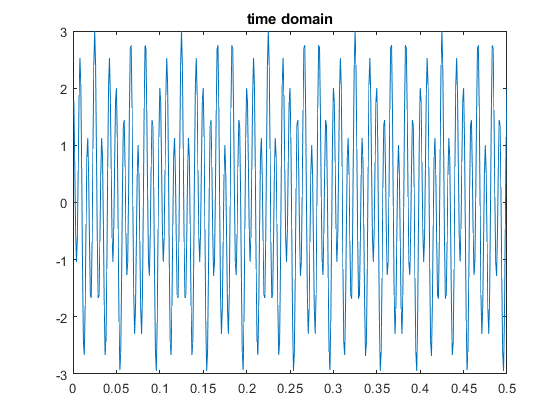

clear
load('dataset1.mat')
fq = 1000;

ft = fft(y);

figure
plot(x,y)
title('time domain')

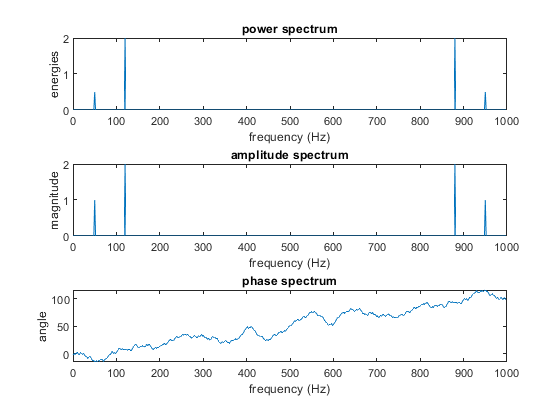

plotfft(ft,fq)

Estimated frequencies from observation of amplitude spectrum:

- Frequency of interest: 120 Hz

- Power line interference: 50 Hz

- -> cutoff frequency for high pass: 110 Hz

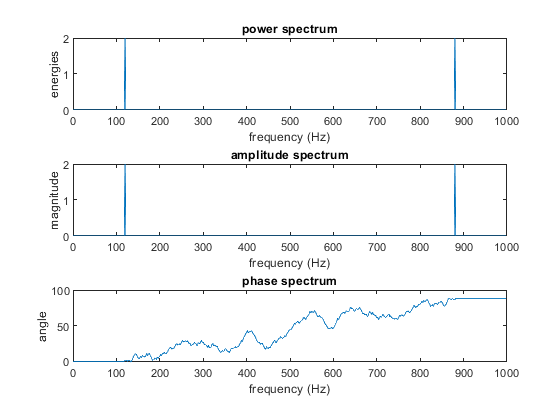

cutoff_f = 118;
cutoff = cutoff_f*length(ft)/fq+1;

filtered = ft;
filtered(1:cutoff) = 0;
filtered(end-cutoff+2:end) = 0;

figure
plotfft(filtered,fq);

## Question 2.5

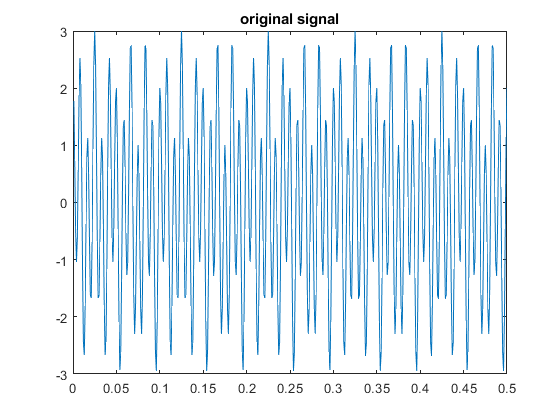

ift = real(ifft(filtered));

figure
plot(x,y)
title('original signal')

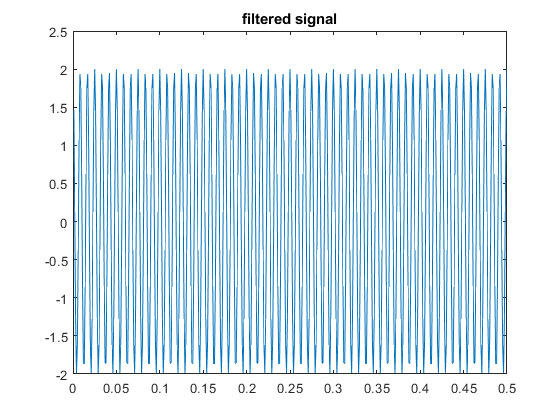

plot(x,ift)
title('filtered signal')

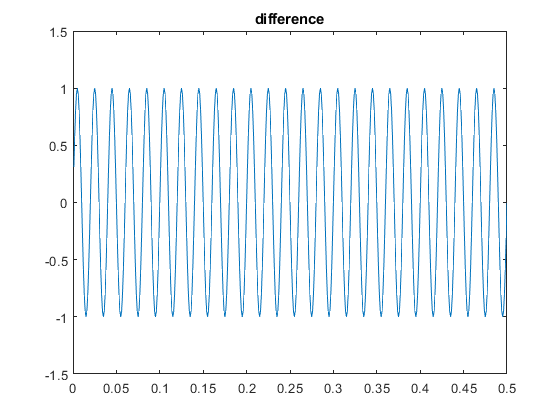

plot(x,y-ift)
title('difference')

## Question 2.6

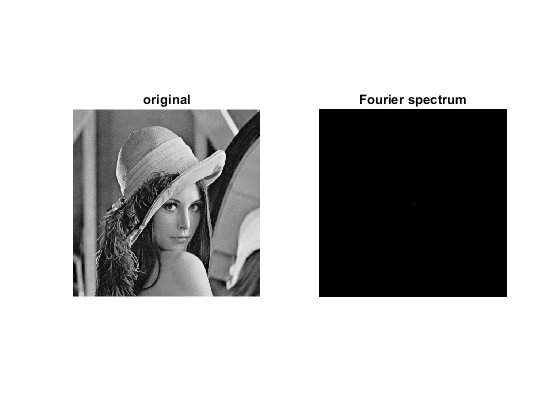

clear

im = double(imread('lena_gray.tif'));
im_fft = fft2(im);
spectrum = fftshift(abs(im_fft));

figure
subplot(1,2,1)
imagesc(im)
colormap gray
title('original')
axis image off
subplot(1,2,2)
imagesc(spectrum)
colormap gray
title('Fourier spectrum')
axis image off

# Why

frequences equally distributed --> all black, white dot in middle: s. notes

## Question 2.7

peak in middle, white dot (due to fftshift)

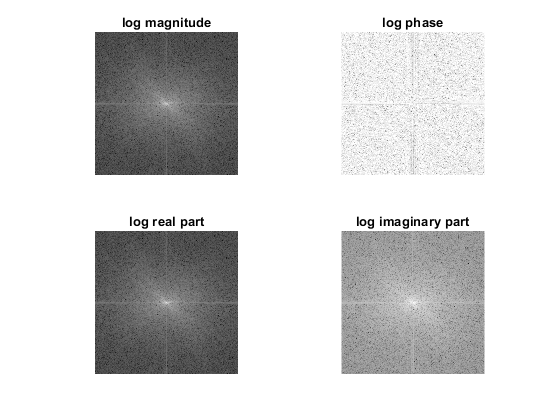

figure
subplot(2,2,1)
imagesc(fftshift(log(abs(im_fft)+1)))
colormap gray
title('log magnitude')
axis image off
subplot(2,2,2)
imagesc(fftshift(real(log(angle(im_fft)+1))))
colormap gray
title('log phase')
axis image off
subplot(2,2,3)
imagesc(fftshift(real(log(im_fft)+1)))
colormap gray
title('log real part')
axis image off
subplot(2,2,4)
imagesc(fftshift(real(log(imag(im_fft)+1))))
colormap gray
title('log imaginary part')
axis image off

## Question 2.8

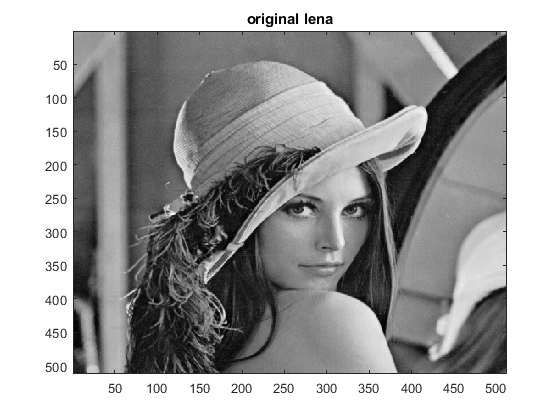

clear

im1 = double(imread('lena_gray.tif'));
im2 = double(imread('peppers_gray.tif'));

imagesc(im1)
title('original lena');

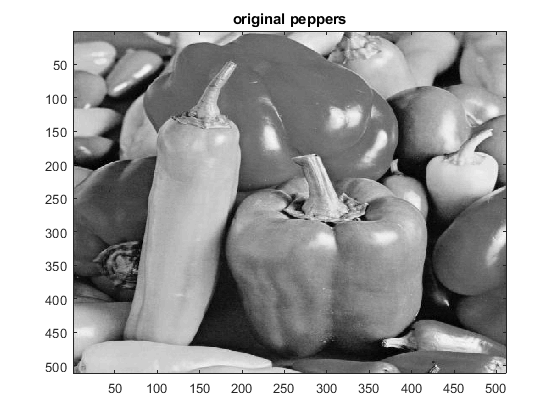

imagesc(im2)
title('original peppers');

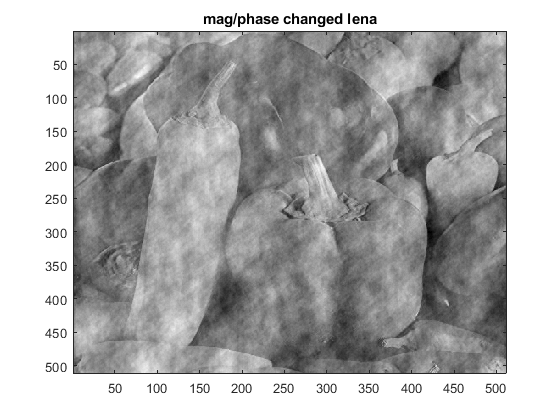


im1_fft = fft2(im1);
im2_fft = fft2(im2);

im1M = abs(im1_fft);
im1P = angle(im1_fft);
im2M = abs(im2_fft);
im2P = angle(im2_fft);

im12_fft = im1M.*(cos(im2P)+1i*sin(im2P));
im21_fft = im2M.*(cos(im1P)+1i*sin(im1P));

im12_ifft = ifft2(im12_fft);
im21_ifft = ifft2(im21_fft);

imagesc(real(im12_ifft))
title('mag/phase changed lena')

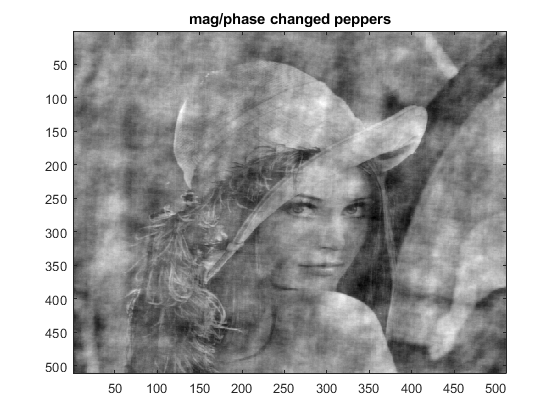

imagesc(real(im21_ifft))
title('mag/phase changed peppers')